**Filippo Galavotti**

Simuleremo un sistema OFDM (Ortogonal Frequency Division Multiplexing) nella fase di Down Link tra una stazione radio base ed un utente. Mapperemo dei simboli con una modulazione PSK/QAM. Oltre ai diagrammi di dispersione, ad occhio e spettro di potenza tracceremo anche gli andamenti della Bit Error Rate (BER), con le curve a waterfall.

Si consideri la seguente struttura di un sistema di trasmissione, rappresentata nella sua forma equivalente in banda base nella Fig. 1: 

        • Sorgente di informazione che genera bit 0 o 1 con la stessa probabilità; 

        • Mappatura dei simboli (generazione della costellazione di simboli desiderata); 

        • Implementazione IFFT 

        • Aggiunta Cyclic Prefix 

        • P/S 

        • Canale di trasmissione ideale; 

        • S/P 

        • Rimozione del Cyclic Prefix 

        • Implementazione FFT 

        • Demodulazione

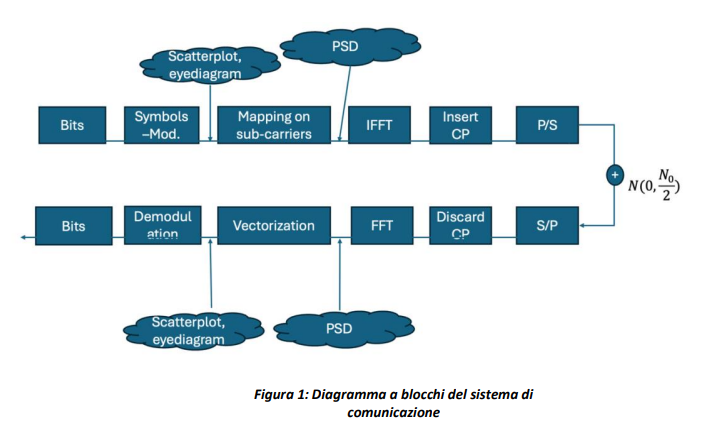

Come prima simulazione consideriamo i parametri Δf=15 kHz, numero di sottoportanti pari a 128 e 4 simboli OFDM. Le modulazioni da testare sono:

- 4-PSK

- 8-PSK

- 16-PSK

close all
clear
clc

## 1. Parameters

%% Parameters
EbN0dB = 0:15;
EbN0 = 10.^(0.1.*EbN0dB);
[Mod, m, T, NRuns, N_sym] = param_choice()

Scelta non valida. Default a PSK
Mancato inserimento di m. m = 2 di default
Mancato inserimento di N_sym. N_sym = 1 di default
Mancato inserimento di T. T = 1e-3 di default
Mancato inserimento di NRuns. NRuns = 100 di default


Mod = 1

m = 2

T = 1.0000e-03

NRuns = 500

N_sym = 1

M = 2^m    % Modulation order, quindi nel nostro caso avrò 16 simboli

M = 4

Definiamo i parametri propri del nostro sistema OFDM.

%N_sym = 1;  % Number of OFDM symbols generated for each subcarrier     %se mettessi 4 la durata totale sarebbe 4* 1/delta f + CP
scs = 15e3;     % Δf: Subcarrier spacing [Hz] (from standard)
t_sym = 1/scs;      % OFDM symbol length [s]  (time domain)
N_sc = 128;        % Total number of subcarriers -> allora la banda totale sarà 15 kHz*N_sc

Definisco i parametri della IFFT, in particolare il numero di campioni in ingresso all'IFFT e la conseguente frequenza di campionamento

N_fft = 128;
fs = scs * N_fft;       % Sampling frequency [Samples/s]

Dopo la IFFT, e prima della trasmissione, aggiungeremo un certo Cycle Prefix **CP.**

t_cp = 1.05e-6;
L_cp = 32; %floor(t_cp * fs);        % CP length in samples   è lungo 32 campioni (lunghezza in campioni del ciclyng prefix)

Calcoliamo i bit ed i simboli della modulazione originale che sono stati trasmessi.

N_sym_tot = N_sc * N_sym;   % Total number of generated symbols per transmission
NBits = N_sym_tot*m;
SNRdB = EbN0dB + 10*log10(m) + 10*log10(N_sc/N_fft);

## 2. Bit Source

Genero i bit casuali e li mappo secondo la modulazione scelta

%% Bit random generator (SOURCE)
EffectiveBits = NBits-mod(NBits,m); %use a number of bits multiple of the modulation order
Bits = round(rand(1,EffectiveBits));

%Mapper
if Mod == 1
    Symbols1 = pskmod(Bits.',M,0.7854,'gray',InputType='bit');
elseif Mod ==2
    Symbols1 = qammod(Bits.',M,'gray',InputType='bit', UnitAveragePower=true);
end

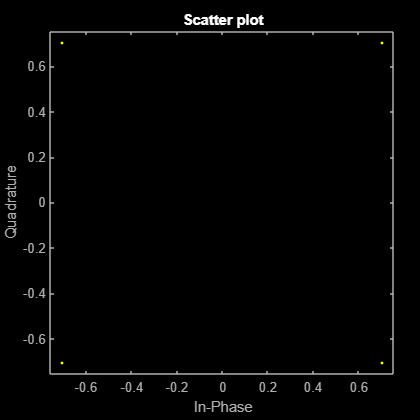

scatterplot(Symbols1);

eyediagram(Symbols1((1:100)),2, 2)

Simulo lo stadio di multiplazione serie-parallelo mettendo i simboli generati in un vettore colonna lungo tanto quanto il numero di simboli. Non specifico il campo delle colonne, perchè il loro numero sarà pari al numero di simboli OFDM che voglio generare

% OFDM grid
tx_grid = reshape(Symbols1, N_sc, []); %lascio vuoto [] perchè non specifico già il numero delle colonne

## 3. IFFT

Implementiamo quindi lo stadio che esegue la IFFT.

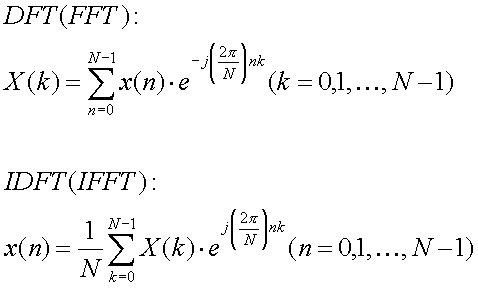

In trasmissione useremo la IFFT. Il suo scopo è quello di "comporre" un simbolo OFDM **x(n), **sommando i simboli **X(k)** (di una modulazione QAM/PSK) che sono mappati nelle frequenze grazie al termine esponenziale.

ifft_sig = ifft(tx_grid, N_fft);

Plottiamo quindi il grafico dei campioni prodotti processati dalla IFFT. Per semplicità ne prendiamo solo la parte reale.

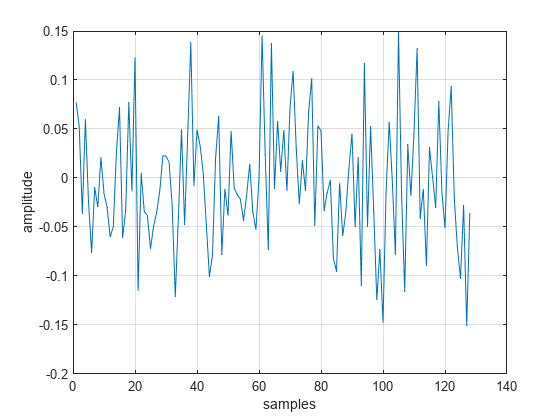

figure
plot(real(ifft_sig(1:128, 1))) 
grid on
xlabel('samples')
ylabel('amplitude')

## 4. Cyclic Prefix

Prima di trasmettere aggiungo al mio segnale un Cyclic Prefix **CP**

% Add Cyclic Prefix
ofdm_sig = [ifft_sig(end - (L_cp - 1):end, :); ifft_sig];
ofdm_sig = reshape(ofdm_sig, [], 1);


Vediamo quindi il grafico dell'ampiezza del simbolo OFDM.

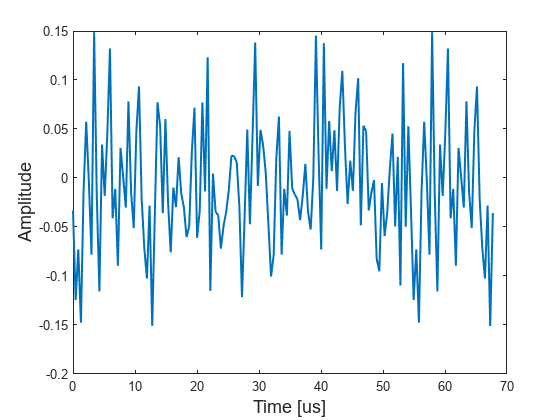

%% Plots
       
toPlot = ofdm_sig(1:min(length(ofdm_sig), 1000));      % Plot first 1e3 samples
x = linspace(0, N_sym*(t_sym + t_cp)*1e6, length(toPlot));
figure;
plot(x, real(toPlot), LineWidth=1.5);
xlabel("Time [us]", FontSize=14)
ylabel("Amplitude", FontSize=14)

Infine posso tracciare lo spettro dell'intero simbolo OFDM. Sarà dato dal contributo di tutte le componenti spettrali di tutte le portanti. Arrivato al ricevitore questo segnale verrà scomposto nelle varie sottoportanti grazie alla FFT.

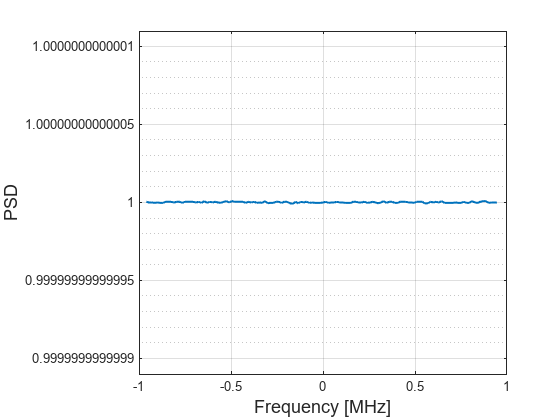

% Spectrum
spectrum = fft(ofdm_sig, N_fft);        % Compute spectrum
shift = (N_fft - N_sc)/2;       % Compute shift to center the spectrum
spectrum = [spectrum(end-(shift-1):end); spectrum(1:N_fft - shift)];    % Shift spectrum
fft_bins = (0:N_fft-1) - N_fft/2;       % Frequency axis
figure;
semilogy(fft_bins .* scs ./ 1e6, abs(spectrum).^2, LineWidth=1.5);
xlabel("Frequency [MHz]", FontSize=14)
ylabel("PSD", FontSize=14)
grid on

## 5. Ricevitore

Consideriamo il canale reale, introducendo quindi un rumore gaussiano bianco prodotto dal canale non ideale.

Al ricevitore vero e proprio avrò le operazioni duali a quelle fatte in trasmissione.

Implementerò un blocco FFT (Fast Fourier Transform), che mi permetterà di scomporre il segnale nelle varie sotto-portanti. Andrò quindi a creare la griglia OFDM.

A questo punto non mi resta che demodulare i simboli sulla griglia così da ricavare i bit dell'informazione.

Infine confronto i bit ricevuti con i bit generati, così da trovare gli errori dovuti al rumore.

% Initialize Bit Error Rate vector
BER = zeros(length(SNRdB), 1);

rng(2)

for k_SNR = 1:length(SNRdB)

    %Initialization of buffer variables
    NErrors=0;
    NTot=0;
    NSymbolErrors=0;
    NTotSymbols=0;
 
    for MC_index = 1:NRuns

        %% Channel
        SNR = 10^(SNRdB(k_SNR)/10);
        N0 = var(ofdm_sig)/SNR;
        noise = sqrt(N0/2)*(randn(size(ofdm_sig))+1i*randn(size(ofdm_sig)));
        rx_sig = ofdm_sig + noise;

        %% RECEIVER
        % Remove Cyclic Prefix
        rx_sig = reshape(rx_sig, [], N_sym);  % Reshape to have one OFDM symbol waveform per column (non ho specificato il numero di righe ma ho specificato il numero di colonne
        rx_sig = rx_sig(L_cp+1:end, :);     % Remove CP (essendo in una rappresentazione matriciale è semplice togliere il CP a tutte le colonne in una volta sola
    
        % FFT
        rx_grid = fft(rx_sig, N_fft);
        rx_grid = rx_grid(1:N_sc, :); %in questo caso non cambia niente perchè ho utilizzato tutte le mie 128 subcarriers per trasmettere l'informazione
        rx_grid = reshape(rx_grid, [], 1);
    
    
        % Decimal to binary conversion
        
        if Mod == 1
            DecodedBits = pskdemod(rx_grid,M,0.7854,'gray',OutputType='bit');
        elseif Mod == 2
            DecodedBits = qamdemod(rx_grid,M,'gray',OutputType='bit', UnitAveragePower=true);
        end
        
        DecodedBits = DecodedBits(:);
    
        % Bit error Rate
        Errors=abs(Bits-DecodedBits.');
        NErrors=NErrors+sum(Errors);
        NTot=NTot+EffectiveBits;
    end
    BER(k_SNR)=NErrors/NTot;
end



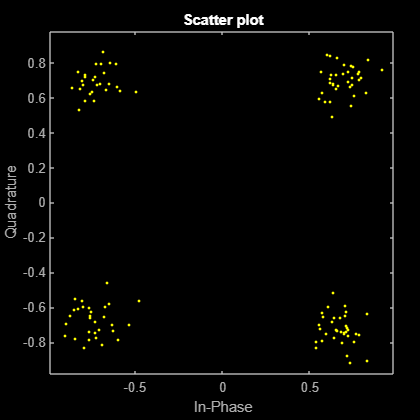

scatterplot(rx_grid)

eyediagram(rx_grid((1:100)),2, 2)

##  6. Bit Error Rate

Giunti a questo punto possiamo tracciare i grafici della probabilità d'errore, che abbiamo calcolato in fase di ricezione, mettendo a confronto i bit ricevuti con quelli trasmessi (noti).

Tracciamo innanzitutto la BER (Bit Error Rate) teorica. Questo è l'andamento calcolato considerando il solo Rapporto Segnale Rumore SNR.

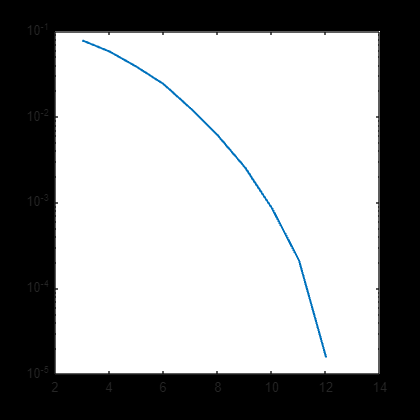

%% BER plot 
figure (1)
semilogy(SNRdB, BER, LineWidth=1.5);

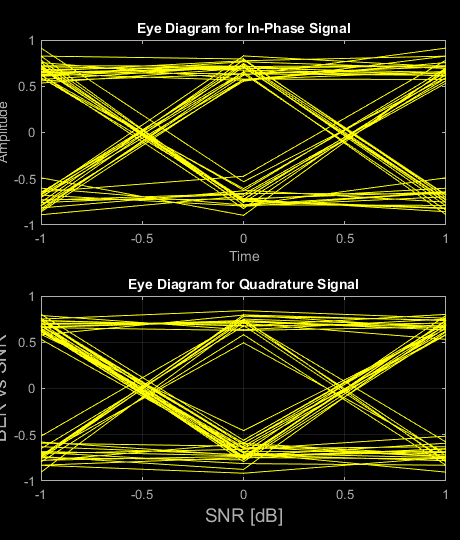

xlabel("SNR [dB]", FontSize=14)
ylabel("BER vs SNR", FontSize=14)
grid on

Facciamo infine un confronto tra la rate degli errori trovati e quella teorica.

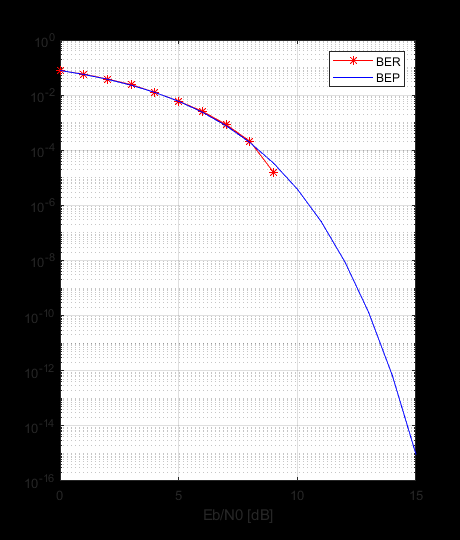

%% Theoretical Ber
if Mod == 1
    if (M == 2 || M == 4)
        BER_th = 1/2 *erfc(sqrt(EbN0*m)*sin(pi/M));
    else
        BER_th = 1/m *erfc(sqrt(EbN0*m)*sin(pi/M));
    end
elseif Mod == 2
    BER_th = 2/m * (sqrt(M)-1)/sqrt(M)*erfc(sqrt(3*m/(2*(M-1))*EbN0));
end

%% Plot
figure (2)
semilogy(EbN0dB,BER,'r*-');
hold on
semilogy(EbN0dB,BER_th,'b');
grid on
title('BER and BER th vs. Eb/N0');
legend('BER','BEP');
xlabel('Eb/N0 [dB]');

function [Mod, m, T, NRuns, N_sym] = param_choice() 
    
    %% richiediamo all'utente la modulazione da utilizzare
    Mod = input(['Scegliere il tipo di modulazione. Default a PSK\n' ... 
        '1. PSK\n' ... 
        '2. QAM\n' ...  
        'Inserisci il numero della modulazione scelta: ']); 
    if Mod == 1 
        disp('Hai scelto la modulazione PSK.'); 
    elseif Mod == 2 
        disp('Hai scelto la modulazione QAM.'); 
    else 
        disp('Scelta non valida. Default a PSK');
        Mod = 1;
    end

    %% Richiede all'utente di inserire m
    m = input("Insirere il numero di bit per simbolo m (default m = 2): "); 
    if isempty(m) 
        disp('Mancato inserimento di m. m = 2 di default'); 
        m = 2; 
    elseif ~isnumeric(m) || m < 1 
        disp('m deve essere un valore numerico e positivo. m = 2 di default'); 
        m = 2; 
    end

    %%richiedere il numero di simboli OFDM da generare
    N_sym = input("Inserire il numero di simboli OFDM da generare N_sym (Default N_sym = 1): ");
    if isempty(N_sym) 
        disp('Mancato inserimento di N_sym. N_sym = 1 di default'); 
        N_sym = 1; 
    elseif ~isnumeric(N_sym) || N_sym <1
        disp('alpha deve essere un valore numerico positivo e diverso da 0. N_sym = 1 di default'); 
        N_sym = 1;
    end
    
    %% Richiede all'utente di inserire T 
    T = input('Inserire tempo di bit T in secondi (Default T = 1e-3): '); 
    if isempty(T) 
        disp('Mancato inserimento di T. T = 1e-3 di default');
        T = 1e-3; 
    elseif ~isnumeric(T) || T < 0 
        disp('T deve essere un valore numerico e positivo. T = 1e-3 di default'); 
        T = 1e-3; 
    end 

    %% richiedere il numero di simulazioni Monte Carlo
    NRuns = input("Inserire il numero di simulazioni Monte Carlo (Default NRuns = 500): ");
    if isempty(NRuns) 
        disp('Mancato inserimento di NRuns. NRuns = 100 di default'); 
        NRuns = 500; 
    elseif ~isnumeric(NRuns) || NRuns <1
        disp('alpha deve essere un valore numerico positivo e diverso da 0. NRuns = 500 di default'); 
        NRuns = 500;
    end
end